# Práctica 1Sistemas Lineales  Aeropendulo Doble

Amelia Hoyos Vélez y Esteban Alvarez Zuluaga

### Introducción 

#### Planteamiento del problema

#### Modelo matemático con descripción de sus elementos.

Supongamos que la fuerza de empuje $T_1$ genera un momento positivo $\vec{M}_1 = l_1 \times T_1$ y que $T_2$ genera un momento negativo $\vec{M}_2 = l_2 \times T_2$. El centro de gravedad del sistema puede no coincidir con el pivote, por lo que el peso del aeropéndulo también produce un momento de fuerza. Dicho momento viene dado por $\vec{M_3} = mgd\sin(\phi)  $, donde $g$ es la aceleración debida a la gravedad, $m$ es la masa del péndulo, $d$ es la distancia desde el pivote hasta el centro de gravedad, y $\phi$ es el ángulo positivo medido entre el eje $y$ negativo y el eje del péndulo. 

Por último, la fuerza de arrastre del aire, que se opone al movimiento, se modela mediante el término $\vec{M_4} = -b\dot{\theta}$ donde $b$ es el coeficiente de amortiguamiento viscoso del aire, $\theta = \frac{\pi}{2} - \phi$ es el ángulo medido respecto a la horizontal positiva y $\dot{\theta}$ es su velocidad angular.

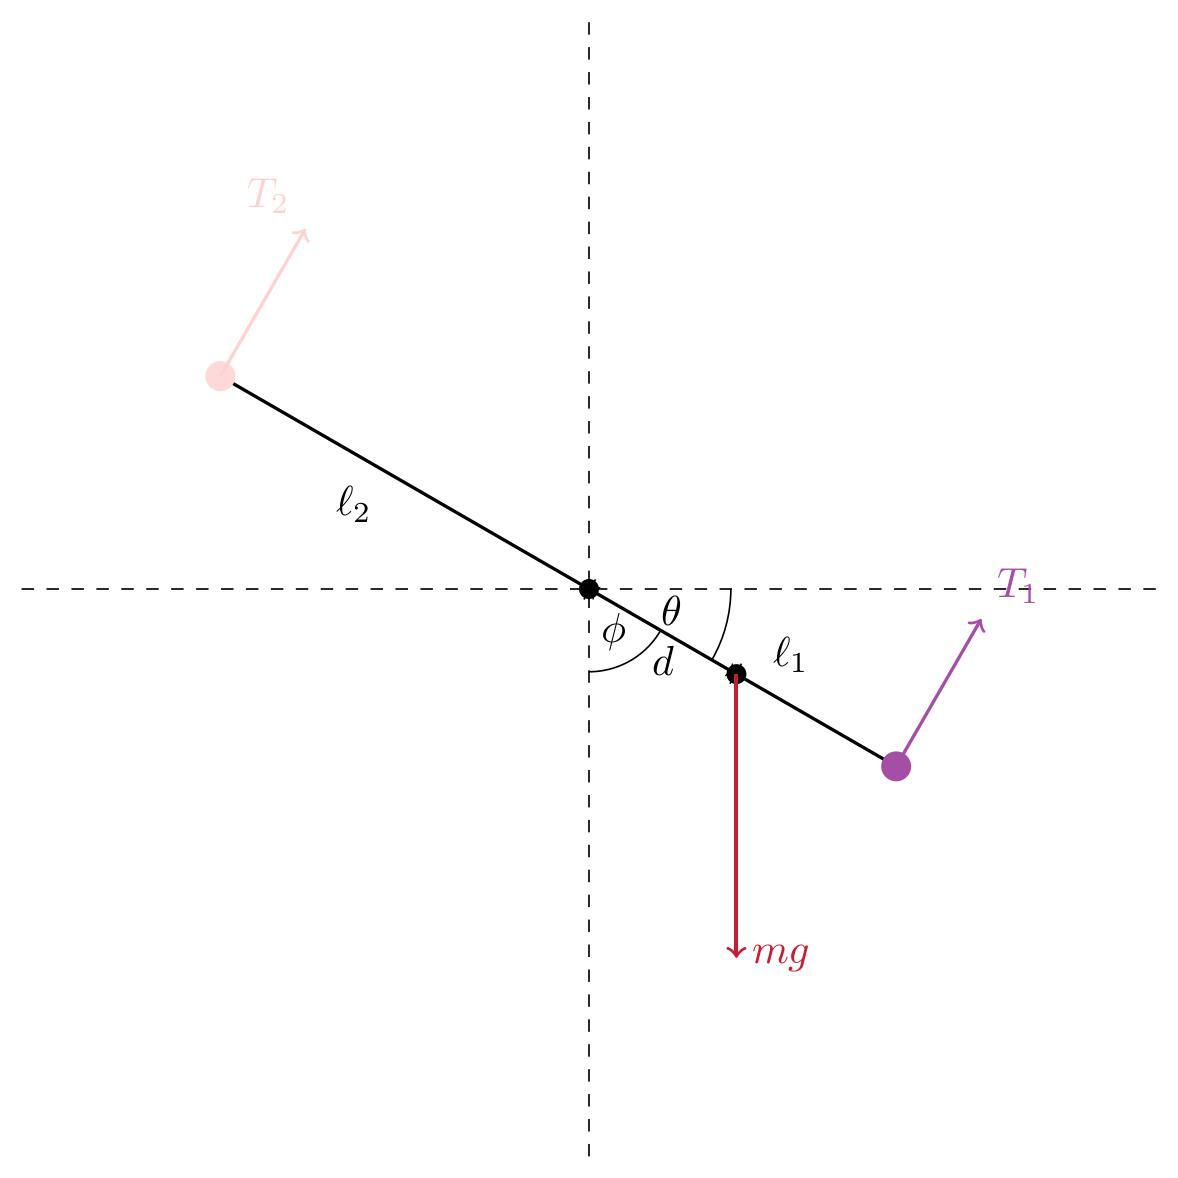

Según la formulación de Newton-Euler que describe la dinámica de sólidos rígidos, 

$J\ddot{\theta} = \sum_{i=1}^4 \vec{M_i} $,

donde $J$ es el momento de inercia rotacional del sistema. La ecuación dinámica del sistema es,

$J\ddot{\theta} = T_1l_1 - T_2l_2 - mgd\sin(\phi) - b\dot{\theta}$.

Podemos reescribir la ecuación como

$J\ddot{\theta} = T_1l_1 - T_2l_2 - mgd\cos\left( \theta\right) - b\dot{\theta}$.

#### Variables y Parámetros del Modelo

Resulta entonces un modelo con los siguientes parámetros y entradas:

**Parámetros:**

**Variables de estado:**

Variables de Control

#### Pregunta Problematizadora

### Métodos

### Resultados

#### Modelo del sistema: Sistema de variables de estado

Con base en el modelo teorico, se realizo la conversión a un sistema en variables de estado. Se tomo X1 como el angulo theta, y x2 como la velocidad angular. De la conversion quedó el sistema:


$$x_1 = \theta \qquad x_2 = \dot{\theta} \qquad u_1 = T_1 \qquad u_2 = T_2

$$



$$\mathbf{x} = \left[\begin{array}{c} x_1 \\ x_2 \end{array}\right] \qquad \mathbf{u} = \left[\begin{array}{c} u_1 \\ u_2 \end{array}\right]$$



$$\left\{\begin{array}{l} \dot{x}_1 = x_2 \\ \dot{x}_2 = \frac{1}{J}\left(u_1 l_1 - u_2 l_2 - mgd\cos x_1 - bx_2\right) \end{array}\right.$$



$$\dot{\mathbf{x}} = \left[\begin{array}{c} x_2 \\ \frac{1}{J}\left(u_1 l_1 - u_2 l_2 - mgd\cos x_1 - bx_2\right) \end{array}\right]$$


#### **Codificación de parámetros y condiciones iniciales**

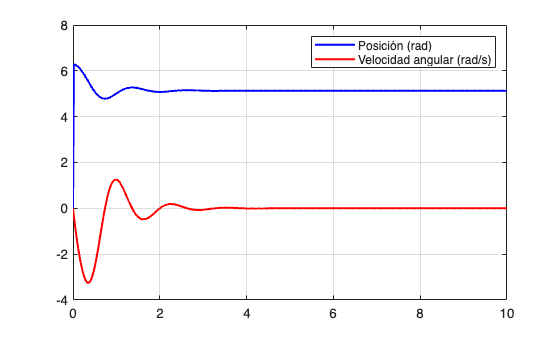

clear; clc; close all;

%% Parámetros físicos
params.m = 0.5;        % Masa (kg)
params.l1 = 0.4;       % Distancia al rotor 1 (m)
params.l2 = 0.2;       % Distancia al rotor 2 (m)
params.d = 0.2;        % Distancia al CG (m)
params.g = 9.81;       % Gravedad (m/s^2)
params.c = 0.1;        % Coeficiente de amortiguamiento (N·m·s/rad)
params.J = params.m*(params.l1^2 + params.l2^2)/3; % Momento de inercia

%% Condiciones iniciales
theta0 = 0;            % Posición en rad
theta_dot0 = 0;        % Velocidad angular en rad/s
x0 = [theta0; theta_dot0];

#### **Modelo computacional codificado**

A continuación se presenta la dinámica del modelo codificada, con una función auxiliar que permite definir el control que se aplicará al sistema. Más adelante se definirá este control de manera algoritmica.

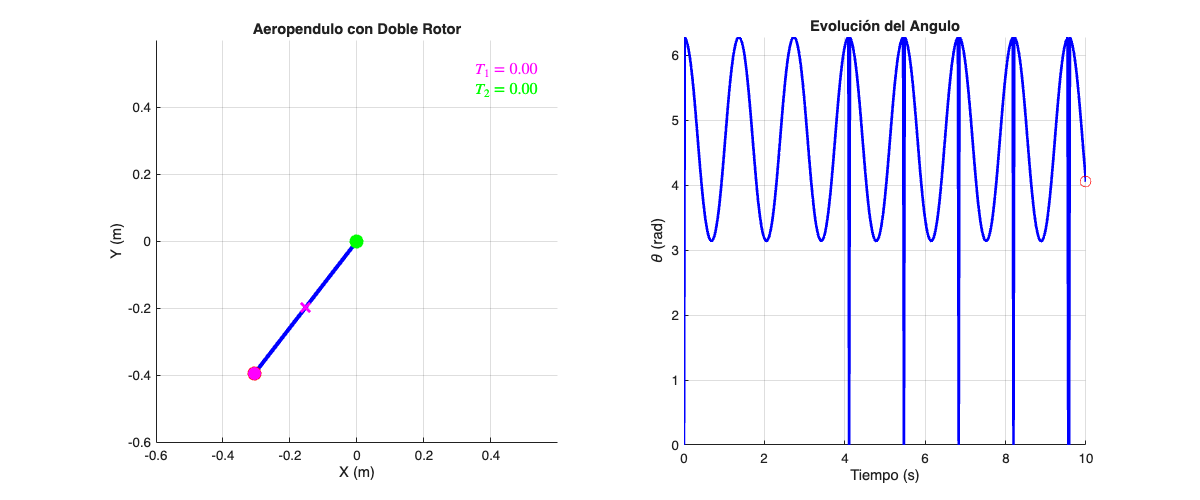

%% ---- Función de dinámica ----
function dx = aeropendulum_dynamics(t,x,params, thrust_fun)

    theta = x(1);
    theta_dot = x(2);
    [T1,T2] = thrust_fun(t, theta, theta_dot);
    theta_ddot = (T1*params.l1 - T2*params.l2 - params.m*params.g*params.d*sin(pi/2 - theta) - params.c*theta_dot)/params.J;
    dx = [theta_dot; theta_ddot];
end
%% ---- Control de empuje ----
function [T1,T2] = thrust_control(t, theta, theta_dot)
% Esta función contendrá en el futuro la manera en que controlaremos
% el empuje de los dos motores.
    T1 = 2;
    T2 = 2;
end


#### Simulación ejemplar

*Condiciones iniciales y parámetros del sistema*

Tomaremos los parámetros previamente seleccionados para la simulación inicial.

*Parámetros de la simulación*

Discretizamos el espacio de 0-10 en 500 puntos.

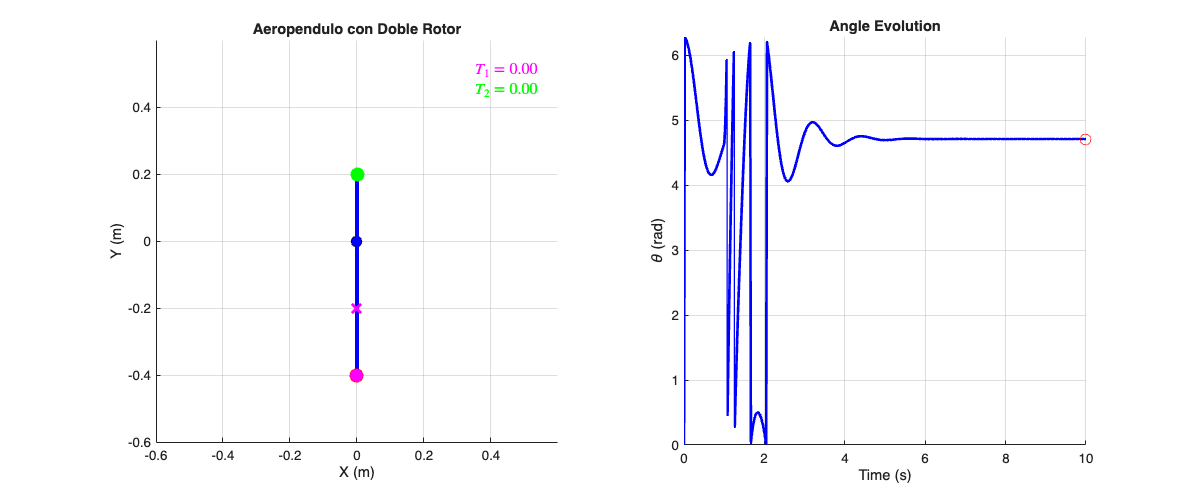

%% Time span
tspan = linspace(0,10,500);

Calculo númerico de la simulación

%% Solve the model as a simple and ordinary differential equation based on an explicit Runge-Kutta (4,5)
[t, sol] = ode45(@(t,x) aeropendulum_dynamics(t,x,params,@thrust_control), tspan, x0);
theta = mod(sol(:,1),2*pi);
theta_dot = sol(:,2);

Gráfico del resultado de la simulación.

plot(t, theta, 'b', t, theta_dot, 'r', 'LineWidth', 1.5);
legend('Posición (rad)', 'Velocidad angular (rad/s)'); grid on;

### Verificación del Modelo

Se procede a verificar el modelo, se probarán distintos escenarios y se compararan con el resultado esperado en la realidad. Se implementó también una función que permite ver una animación del aeropendulo a través del tiempo de acuerdo a la ecuación diferencial. Usando esta función, se puede verificar que el comportamiento del pendulo represente visualmente lo esperado en casos simples de la realidad.

#### Función de la animación de la dinámica del aeropendulo

function simulate_aeropendulum(dynamics_fun, thrust_fun, params, tspan, x0)

    l1 = params.l1;
    l2 = params.l2;
    d  = params.d;
    
    %% Solve the model as a simple and ordinary differential equation based on an explicit Runge-Kutta (4,5)
    [t, sol] = ode45(@(t,x) dynamics_fun(t,x,params,thrust_fun), tspan, x0);
    theta = mod(sol(:,1),2*pi);
    theta_dot = sol(:,2);
    
    %% Create an animated figure to see the behavior
    figure('Position',[100 100 1200 500])
    
    % Pendulum how it is seen in the human eyes
    subplot(1,2,1)
    axis equal
    axis([-0.6 0.6 -0.6 0.6])
    grid on
    xlabel('X (m)')
    ylabel('Y (m)')
    title('Aeropendulo con Doble Rotor')
    hold on
    
    % Color some things
    pivot = plot(0,0,'ko','MarkerSize',8,'MarkerFaceColor','b');
    bar = plot([0 0],[0 0],'b-','LineWidth',3);
    r1 = plot(0,0,'ro','MarkerSize',10,'MarkerFaceColor','m');
    r2 = plot(0,0,'go','MarkerSize',10,'MarkerFaceColor','g');
    cg = plot(0,0,'mx','MarkerSize',10,'LineWidth',2);
    
    label_T1 = text(0.95, 0.95, '$T_1$', ...
        'Units','normalized','FontSize',12,...
        'HorizontalAlignment','right','VerticalAlignment','top',...
        'Color','m','Interpreter','latex');
    
    label_T2 = text(0.95, 0.90, '$T_2$', ...
        'Units','normalized','FontSize',12,...
        'HorizontalAlignment','right','VerticalAlignment','top',...
        'Color','g','Interpreter','latex');
    
    % ---- Angle theta plot ----
    subplot(1,2,2)
    grid on
    xlabel('Tiempo (s)')
    ylabel('\theta (rad)')
    title('Evolución del Angulo')
    hold on
    angle_line = animatedline('Color','b','LineWidth',2);
    current_point = plot(0,0,'ro','MarkerSize',8);
    ylim([0 2*pi])
    xlim([tspan(1) tspan(end)])
    
    %% Animation loop
    for k = 1:length(t)
        th = theta(k);
        thdot = theta_dot(k);
    
        % Positions
        x1 =  l1*cos(th);   y1 =  l1*sin(th);
        x2 = -l2*cos(th);   y2 = -l2*sin(th);
        xcg = d*cos(th);    ycg = d*sin(th);
    
        set(bar,'XData',[x2 x1],'YData',[y2 y1]);
        set(r1,'XData',x1,'YData',y1);
        set(r2,'XData',x2,'YData',y2);
        set(cg,'XData',xcg,'YData',ycg);
    
        % Thrust arrows
        delete(findall(gca,'Type','quiver'))
        [T1,T2] = thrust_fun(t(k), th, thdot);
    
        set(label_T1,'String',sprintf('$T_1 = %.2f$',T1));
        set(label_T2,'String',sprintf('$T_2 = %.2f$',T2));
    
        scale = 0.05;
        perp = th + pi/2;
    
        quiver(x1,y1,scale*T1*cos(perp),scale*T1*sin(perp),0,'r','LineWidth',1.5);
        quiver(x2,y2,scale*T2*cos(perp),scale*T2*sin(perp),0,'g','LineWidth',1.5);
    
        addpoints(angle_line,t(k),th);
        set(current_point,'XData',t(k),'YData',th);
    
        drawnow
        pause(0.02)
    end
end

#### **Simulación sin empuje ni rozamiento (Pendulo Simple)**

Con una simulación sin empuje ni rozamiento, y con un solo brazo de palanca, se espera que el sistema se comporte como un pendulo simple que no cese de oscilar de manera aproximadamente sinusoidal. Se toman los siguientes parámetros y entradas.

%% PRUEBA COMO PÉNDULO SIMPLE

%% Parámetros físicos
params.m = 0.5;        % Masa (kg)
params.l1 = 0.5;       % Distancia al rotor 1 (m)
params.l2 = 0;       % Distancia al rotor 2 (m)
params.d = 0.25;        % Distancia al CG (m)
params.g = 9.81;       % Gravedad (m/s^2)
params.c = 0;        % Coeficiente de amortiguamiento (N·m·s/rad)
params.J = params.m*(params.l1^2 + params.l2^2)/3; % Momento de inercia

%% Condiciones iniciales
theta0 = 0;            % Posición en rad
theta_dot0 = 0;        % Velocidad angular en rad/s
x0 = [theta0; theta_dot0];

%% ---- Control de empuje ----
function [T1,T2] = thrust_control_zero(t, theta, theta_dot)
% Esta función contendrá en el futuro la manera en que controlaremos
% el empuje de los dos motores.
    T1 = 0;
    T2 = 0;
end

Habiendo definido los parámetros se realiza la simulación.

simulate_aeropendulum(@aeropendulum_dynamics, @thrust_control_zero, params, tspan, x0)

Se esperaba un comportamiento de pendulo simple, sinusoidal, lo cual fue confirmado.

#### **Validación de formula de g para caso de pendulo simple**

#### **Simulación con distintos valores de l1 y l2**

#### **Simulación con distintos coeficientes de fricción**

Con una simulación con un nivel muy bajo de rozamiento, se espera que oscile de manera prolongada hasta estabilizarse. Con un alto coeficiente de fricción se espera que el sistema este sobreamortiguado, y que se estabilize más rápido. A continuación se presenta el ejemplo con un bajo coeficiente de fricción, se espera oscilación que disminuya lentamente.

%% PRUEBA CON BAJO COEFICIENTE DE FRICCIÓN

%% Parámetros físicos
params.m = 0.5;        % Masa (kg)
params.l1 = 0.4;       % Distancia al rotor 1 (m)
params.l2 = 0.2;       % Distancia al rotor 2 (m)
params.d = 0.2;        % Distancia al CG (m)
params.g = 9.81;       % Gravedad (m/s^2)
params.c = 0.01;        % Coeficiente de amortiguamiento (N·m·s/rad)
params.J = params.m*(params.l1^2 + params.l2^2)/3; % Momento de inercia

%% Condiciones iniciales
theta0 = 0;            % Posición en rad
theta_dot0 = 0;        % Velocidad angular en rad/s
x0 = [theta0; theta_dot0];

%% Para el control tomamos ambos motores en 2 N

%simulate_aeropendulum(@aeropendulum_dynamics, @thrust_control, params, tspan, x0)

Se evidencia un patrón sinusoidal como se espera, que lentamente converge a un equilibrio. Debido al empuje de los rotores, no se estabiliza en $\frac{\pi }{2}$, sino en otro valor. A continuación se presenta el ejemplo con un alto coeficiente de fricción, se espera minima oscilación y estabilización rápida.

%% PRUEBA CON ALTO COEFICIENTE DE FRICCIÓN

%% Parámetros físicos (Solo se cambia la fricción)
params.c = 0.9;        % Coeficiente de amortiguamiento (N·m·s/rad)

%% Condiciones iniciales
theta0 = 0;            % Posición en rad
theta_dot0 = 0;        % Velocidad angular en rad/s
x0 = [theta0; theta_dot0];

%% Para el control tomamos ambos motores en 2 N

simulate_aeropendulum(@aeropendulum_dynamics, @thrust_control, params, tspan, x0)

No se evidencia fenómeno oscilatorio, y como se esperaba, se estabiliza rápidamente.

#### **Simulación con empuje unilateral**

Retornamos a los parámetros originales, y cambiamos el empuje para que sea de un solo motor, en un valor alto. Se espera que sea capaz de sobreponerse al peso, y que el pendulo comienze a dar vueltas en sentido antihorario debido a la influencia del torque unilateral T1.

%% PRUEBA CON EMPUJE UNILATERAL
%% Parámetros físicos
params.m = 0.5;        % Masa (kg)
params.l1 = 0.4;       % Distancia al rotor 1 (m)
params.l2 = 0.2;       % Distancia al rotor 2 (m)
params.d = 0.2;        % Distancia al CG (m)
params.g = 9.81;       % Gravedad (m/s^2)
params.c = 0.1;        % Coeficiente de amortiguamiento (N·m·s/rad)
params.J = params.m*(params.l1^2 + params.l2^2)/3; % Momento de inercia


%% Condiciones iniciales
theta0 = 0;            % Posición en rad
theta_dot0 = 0;        % Velocidad angular en rad/s
x0 = [theta0; theta_dot0];

%% Para el control tomamos un solo motor con 10N
%% ---- Control de empuje ----
function [T1,T2] = unilateral_thrust_control(t, theta, theta_dot)
    T1 = 10;
    T2 = 0;
end

simulate_aeropendulum(@aeropendulum_dynamics, @unilateral_thrust_control, params, tspan, x0)

Como se esperaba, debido a la fuerza exclusivamente en un extremo, el pendulo comeinza a girar rápidamente en la dirección del torque T1, corroborando asi la intuición fisica. 

#### **Angulo de Estabilización con control constante**

Tabla con el angulo de estabilización dado un control constante.

%% PRUEBA CON EMPUJE UNILATERAL
%% Parámetros físicos
params.m = 0.5;        % Masa (kg)
params.l1 = 0.4;       % Distancia al rotor 1 (m)
params.l2 = 0.2;       % Distancia al rotor 2 (m)
params.d = 0.2;        % Distancia al CG (m)
params.g = 9.81;       % Gravedad (m/s^2)
params.c = 0.1;        % Coeficiente de amortiguamiento (N·m·s/rad)
params.J = params.m*(params.l1^2 + params.l2^2)/3; % Momento de inercia


%% Condiciones iniciales
theta0 = 0;            % Posición en rad
theta_dot0 = 0;        % Velocidad angular en rad/s
x0 = [theta0; theta_dot0];

%% Para el control tomamos un solo motor con 10N
%% ---- Control de empuje ----
function [T1,T2] = constant_thrust_control(c, t, theta, theta_dot)
    T1 = c;
    T2 = c;
end


Gráfico del resultado de la simulación.

- Ángulo de estabilización por fuerza de control-> comprobación de punto de equilibrio

- Simular Fuerza necesaria para dar giro completo mas rapida

#### Simulación con cambio de entradas (uno no y otro si, y los dos si)

%% Parámetros físicos
params.m = 0.5;
params.l1 = 0.4;
params.l2 = 0.2;
params.d = 0.2;
params.g = 9.81;
params.c = 0.1;
params.J = params.m*(params.l1^2 + params.l2^2)/3;
tspan = linspace(0,10,500);
x0 = [0; 0];

**Entrada en escalón**

function [T1,T2] = thrust_step(t, theta, theta_dot)
    T1 = 2;
    T2 = 2;
end

simulate_aeropendulum(@aeropendulum_dynamics, @thrust_step, params, tspan, x0)

**Entrada Sinusoidal**

function [T1,T2] = thrust_sin(t, theta, theta_dot)
    T1 = 2*sin(2*pi*0.5*t) + 2;
    T2 = 2*sin(2*pi*0.5*t) + 2;
end

simulate_aeropendulum(@aeropendulum_dynamics, @thrust_sin, params, tspan, x0)

**Entrada Impulso**

function [T1,T2] = thrust_dirac(t, theta, theta_dot)
    T1 = 100*(t > 1 & t < 1.08);
    T2 = 100*(t > 1 & t < 1.08);
end

simulate_aeropendulum(@aeropendulum_dynamics, @thrust_dirac, params, tspan, x0)

#### Simulación con el cambio de dos parámetros

### Discusión

#### Interpretación de los resultados

### Bibliografía